B2_1 fft

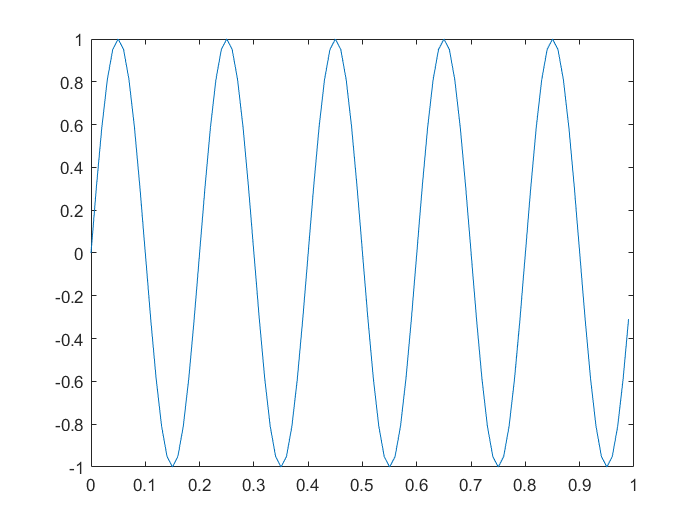

clear
Fs = 100; % Sampling frequency
T = 1/Fs; % Sampling period
t = 0:T:1-T; % Time vector
y = sin(2*pi*5*t); % omgea = 5
% y = sin(2*pi*5*t) +cos(2*pi*2*t + pi/3) ;
plot(t,y)

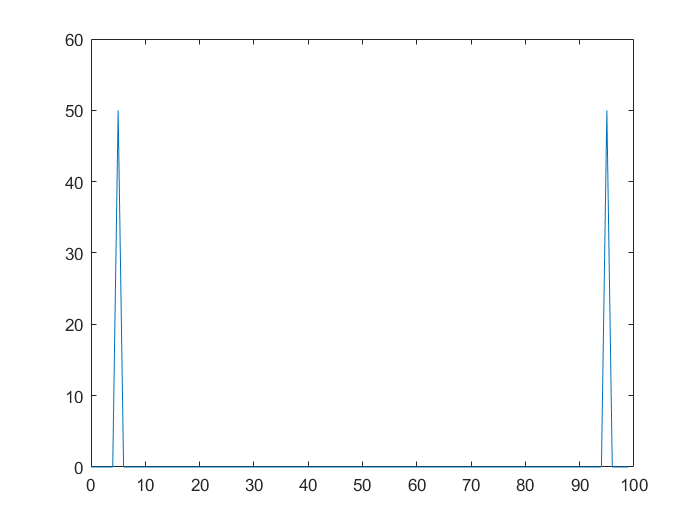


Y = fft(y);
f = (0:length(Y)-1)*Fs/length(Y); % scale the frequency distance by sampling frequency
plot(f,abs(Y));

the spikes in magnitude correspond to the signal's frequency components of 5 Hz

mirror copy of the spike corresponds to the signal's negative frequencies

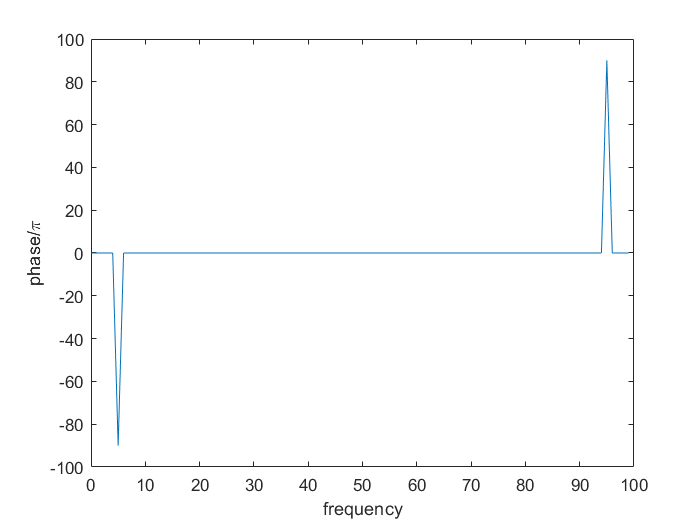

% Z = fftshift(Y); % fftshift can make the low frequency to the center
% f = (-length(Y)/2:length(Y)/2-1)*Fs/length(Y);
% plot(f,abs(Z))
% xlabel('frequency')
% ylabel('amplitude')
Z = Y;
tol = 1e-6; 
Z(abs(Z)<tol)=0; % removing small-magnitude transform values
theta = angle(Z);
plot(f,theta*180/pi) % minus 90 degrees of cos() function
xlabel('frequency')
ylabel('phase/\pi')

% Z~=0

B2_2 change the frequency of the sine wave 

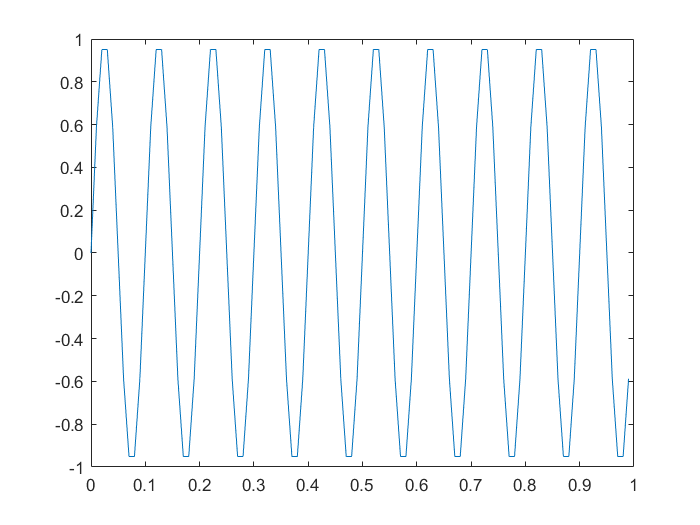

y2 = sin(2*pi*10*t); % omgea = 10
% y2 = sin(2*pi*10*t) + cos(2*pi*2*t+pi/3); 
plot(t,y2)

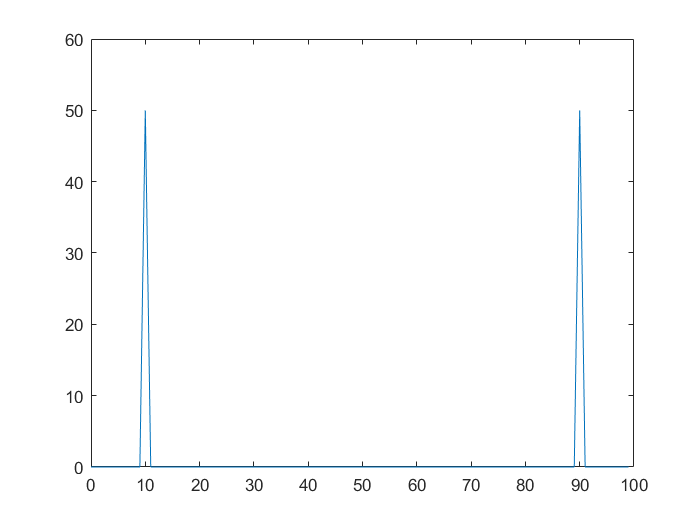

Y2 = fft(y2);
f2 = (0:length(Y2)-1)*Fs/length(Y2);
plot(f2,abs(Y2));

the spike change to 2

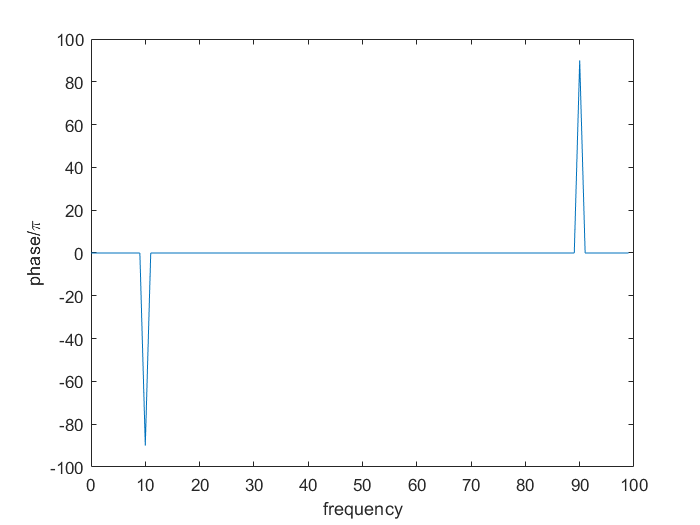

tol = 1e-6;
Z2 = Y2;
Z2(abs(Z2)<tol)=0;
theta2 = angle(Z2);
plot(f2,theta2*180/pi)
xlabel('frequency')
ylabel('phase/\pi')

B2_3 ifft inverse Fourier transform

z = ifft(Y)

z =     0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


plot(t,z)

sum(z-y)

ans = -3.4427e-16

B2_4

If the signal of input has zero imaginary part. The ifft result is 0 on imaginary part

the values of the imaginary part of the signal give the information about the phase shift

Because the Fourier transform can be inversed